# Laboratorio 2

## Mateo Fernández (202320768), Gabriela Villalba y Gabriel Sanchez (202420981)

## Punto 1.

%1.1
Vref = 5.000;
A = [5.210, 5.220, 5.210, 5.220, 5.210];
B = [4.910, 5.080, 5.000, 4.980, 5.030];

xS = single([1 1e3 1e8])
xD = double([1 1e3 1e8])
sesgo = media - Vref;
Ea = abs(media - Vref);
Er = Ea / abs(Vref);
Epct = 100 * Er;
end

[media_A, std_A, sesgo_A, Ea_A, Er_A, Epct_A] = calcular_metricas(A, Vref);
[media_B, std_B, sesgo_B, Ea_B, Er_B, Epct_B] = calcular_metricas(B, Vref);

%1.2

numero_medicion = 1:5;

figure

scatter(numero_medicion, A, 45, 'b', 'filled')
hold on
scatter(numero_medicion, B, 45, 'r', 'filled')
yline(Vref, 'k--', 'LineWidth', 1.5)
hold off

xlabel('Número de medición')
ylabel('Voltaje [V]')
title('Comparación de mediciones: Instrumento A vs B')
legend('Instrumento A', 'Instrumento B','V_{ref} = 5.000 V', 'Location', 'best')
grid on

%Tabla comparativa
nombres_columnas= {'Instrumento','Media','Desv_Std','Sesgo','Ea','Er','E_pct'};
tabla_metricas = table({'A';'B'}, [media_A;media_B], [std_A;std_B], [sesgo_A;sesgo_B], ...
    [Ea_A;Ea_B], [Er_A;Er_B], [Epct_A;Epct_B],'VariableNames',nombres_columnas)

%1.3
b_A = media_A - Vref;
A_corr= A - b_A;

[media_Acorr, std_Acorr, sesgo_Acorr, Ea_Acorr, Er_Acorr, Epct_Acorr] = calcular_metricas(A_corr, Vref);

tabla_metricas_corr = table({'A (original)';'A (corregida)'}, [media_A;media_Acorr], [std_A;std_Acorr], ...
    [sesgo_A;sesgo_Acorr], [Ea_A;Ea_Acorr], [Er_A;Er_Acorr], [Epct_A;Epct_Acorr], ...
    'VariableNames', {'Version','Media','Desv_Std','Sesgo','Ea','Er','E_pct'})

## Punto 2.

%a.
xS = single([1 1e3 1e8]);
xD = double([1 1e3 1e8]);

%b.
disp("Bytes ocupados por arreglo")

Bytes ocupados por arreglo


w1 = whos("xS").bytes

w1 = 12

w2 = whos("xD").bytes

w2 = 24

disp("Bytes por elemento" + newline + "xS")

Bytes por elemento
xS


w1_ele = whos("xS").bytes/numel(xS)

w1_ele = 4

disp("xD")

xD


w2_ele = whos("xD").bytes/numel(xD)

w2_ele = 8


%c. 
disp("Separación local")

Separación local


separacion_xS = eps(xS)

separacion_xS = 1×3 single row vector
    0.0000    0.0001    8.0000


separacion_xD = eps(xD)

separacion_xD = 1.0e-07 *

    0.0000    0.0000    0.1490



disp("Separación elemento a elemento")

Separación elemento a elemento


separacion_s1 = eps(single(1))

separacion_s1 = single
1.1921e-07

separacion_s2 = eps(single(1e3))

separacion_s2 = single
6.1035e-05

separacion_s3 = eps(single(1e8))

separacion_s3 = single
8


separacion_d1 = eps(double(1))

separacion_d1 = 2.2204e-16

separacion_d2 = eps(double(1e3))

separacion_d2 = 1.1369e-13

separacion_d3 = eps(double(1e8))

separacion_d3 = 1.4901e-08


%d.
disp("Minimos y máximos dependiendo del tipo de variable")

Minimos y máximos dependiendo del tipo de variable


min_d = realmin("double")

min_d = 2.2251e-308

max_d = realmax("double")

max_d = 1.7977e+308

flint_d = flintmax("double")

flint_d = 9.0072e+15


min_s = realmin("single")

min_s = single
1.1755e-38

max_s = realmax("single")

max_s = single
3.4028e+38

flint_s = flintmax("single")

flint_s = single
16777216

format long
%e.
T = table( ...
    ["single"; "double"], ...
    [w1_ele; w2_ele], ...
    [realmin('single'); realmin('double')], ...
    [realmax('single'); realmax('double')], ...
    [flintmax('single'); flintmax('double')], ...
    [eps(single(1)); eps(double(1))], ...
    [eps(single(1e3)); eps(double(1e3))], ...
    [eps(single(1e8)); eps(double(1e8))], ...
    'VariableNames', {'Clase','BytesPorElemento','Realmin','Realmax', ...
    'Flintmax','Eps1','Eps1e3','Eps1e8'});
T

T = 2×8 table
     Clase      BytesPorElemento      Realmin         Realmax         Flintmax          Eps1           Eps1e3          Eps1e8   
    ________    ________________    ____________    ____________    ____________    ____________    ____________    ____________

    "single"           4            1.175494e-38    3.402823e+38    1.677722e+07    1.192093e-07    6.103516e-05               8
    "double"           8                       0             Inf    9.007199e+15    2.220446e-16    1.136868e-13    1.490116e-08



%2.2
aS = single(1e16);
bS = single(-1e16);
cS = single(1);

aD = double(1e16);
bD = double(-1e16);
cD = double(1);

f1_s = single(0.1) + single(0.2) - single(0.3);
f1_d = 0.1 + 0.2 - 0.3;

f2_s = sin(single(pi));
f2_d = sin(pi);

f3_s = (aS + bS) + cS;
f3_d = (aD + bD) + cD;

f4_s = aS + (bS + cS);
f4_d = aD + (bD + cD);

T_22 = table( ...
    ["0.1 + 0.2 - 0.3"; "sin(pi)"; "(a+b)+c"; "a+(b+c)"], ...
    [f1_s; f2_s; f3_s; f4_s], ...
    [f1_d; f2_d; f3_d; f4_d], ...
    'VariableNames', {'Expresion','ResultadoSingle','ResultadoDouble'});
disp(T_22)

        Expresion        ResultadoSingle      ResultadoDouble   
    _________________    _______________    ____________________

    "0.1 + 0.2 - 0.3"                 0     5.55111512312578e-17
    "sin(pi)"             -8.742278e-08     1.22464679914735e-16
    "(a+b)+c"                         1                        1
    "a+(b+c)"                         0                        0



Análisis: Redondeo y asociatividad

Los resultados de las expresiones 0.1+0.2-0.3 y $sin(\pi)$ si bien de forma analítica son equivalentes a 0, en las representaciones de precisión finita double y single que utilizamos, los valores decimales involucrados en primera expresión y el valor $\pi$ en general no tienen una representación binaria que sea exacta y finita. El paquete numérico de MATLAB resuelve este tipo de operaciones guardando una aproximación de dichos valores y luego redondeando los resultados de las operaciones aritméticas. Se concluye entonces que los residuos de las operaciones son consecuencia del redondeo pero no evidencia de que las identidades matemáticas son falsas.

Por otra parte, las expresiones involucrando a las variables a, b y c demuestran que la suma punto flotante no es associativa, es decir, $(a+b)+c \neq a + (b+c)$. La primera operación resulta en 1 ya que $a+b = 10^{16 }- 10^{16} = 0$ por lo que solo es necesario representar el $c = 1$. En el segundo caso $b+c = -10^{16} + 1 \approx -10^{16}$ ya que a esa escala eps(1e16) = 2 por lo que dicho caso en particular no se puede representar exactamente y debe ser redondeado, en este caso, al entero anterior. De esta manera, la operación termina siendo $a + (b+c) \approx 10^{16} - 10^{16} = 0$. De esta manera, se puede concluir que el orden de las operaciones afecta el resultado computado incluso si las expresiones son matematicamente identicas.

%2.3

z = single(1.42*10^38)

z = single
   1.4200000e+38


z1 = double(1.42*10^38)

z1 =      1.420000000000000e+38


alpha = 2.5*single(1.42*10^38)

alpha = single
   Inf


beta = 2.5*double(1.42*10^38)

beta =      3.550000000000000e+38


Análisis: Overflow

El valor $1.42\cdot10^{38}$ es representable en ambos formatos antes de la multiplicación. Sin embargo, despues de la operación el resultado esperado es $3.55 \cdot10^{38}$. No obstante, con los resultados previos se puede observar que $realmax(single) \approx 3.4028\cdot 10^{38}$, que es menor al resultado obtenido indicando que hay overflow y, por lo tanto, el resultado es $Inf$. Si bien la tabla obtenida muestra que el máximo del double es $Inf$, su numero máximo para representar es $1.7977\cdot 10^{308}$ que está muy por encima del resultado de la operación indicando que no hay overflow.

Análisis: $single$ vs $double$

El formato single utiliza 4 bytes por elemento, mientras tanto, double utiliza 8. Esa capacidad extra de almacenamiento le permite al formato double una mejor presición y un rango de representación mayor. Particularmente, los resultados obtenidos para eps(1) muestran que para el formato single el espacio entre valores representables es $1.1921\cdot 10^{-7}$ mientras que para el formato double es de $2.2204 \cdot 10^{-16}$. Es decir, cerca de la unidad, el formato double puede distinguir incrementos casi $5.37 \cdot 10^8$ más pequeños que el formato single.

Los valores obtenidos en la sección 2.1 muestran que los numeros punto flotantes no estan espaciados uniformemente sobre los reales. La función eps(x) de MATLAB nos permite ver la distancia entre el valor x y el siguiente valor representable de su orden. Los resultados nos muestran el caso patológico de el formato single. eps(1) =$1.1921\cdot 10^{-7}$ y eps($10^8$) = 8; es decir cuando $x \approx 1$ podemos representar con buena precisión la mayoría de enteros pero si x = $10^8$ habrá una banda de 8 unidades en la que todos esos valores tendrán que ser aproximados bien sea al siguiente o al anterior valor representable.

El aumento en el espaciado entre valores ocurre por la representación de punto flotante normalizada $x = (-1)^s(1.f)\cdot 2^e$ donde $f$(mantissa) puede representar un numero fijo de digitos y $e$ (exponente) cambia la escala de dicho numero. A penas una magnitud excede una potencia de dos, el exponente aumenta para compensar ese crecimiento. La operación resulta problemática para la precisión absoluta de los valores, pues si bien los valores que representa la mantissa mantendrar un numero finito de bits, cada incremento de orden de magnitud con el exponente multiplicará por dos al valor, esto no solo equivale a que el valor será mayor en magnitud sino que la diferencia entre dicho valor y sus contiguos aumentará por dos también. Cuando el proceso se repite para alcanzar ordenes de magnitud mayores es claro entonces que la diferencia se hace mayor por el incremento del exponente y los espacios entre valores crecen en el orden de $2^e$.

## Punto 3.

## Punto 4.

## Punto 5.

V = 12 + 0.01*d(8)
R = 220 + 0.5*d(9)
delta_v = 0.005*(1+d(7)/10) %COTAS MAXIMAS DEL ERROR ABSOLUTO
delta_r = 0.2 + 0.05*d(8)

function potencia = calcular_potencia(V, R)
    potencia = V*V/R;
end





## Punto 6.

**Evaluación de la corrección lineal de errores de ganancia y offset en un ADC de 12 bits para mejorar la conversión de voltaje**

Sistema estudiado: Conversión análoga-digital (ADC) en los microcontroladores F2810/F2811/F2812

Magnitud medida o calculada: Código ADC representando el voltaje de entrada

Instrumento o algoritmo utilizado: ADC + calibración de ganancia y offset de dos puntos

Valor de referencia o especificación disponible: Entradas de voltaje de referencia

Cusa del error descrita en la fuente: Errores en el offset y ganancia del ADC

Un ADC ideal de 12 bits sin error de ganancia ni offset se describe como:

$x_{ideal} = \frac{4095}{3.0V} \cdot mi \cdot V_{in}$ donde $y$ = Conteo de salida, $x$ = Voltaje de entrada  $mi =  1.0 $ equivalente a la ganancia ideal.

Es decir, el ADC se comporta como una función afin traduciendo el rango $[0V,3V]$ a un conteo digital equivalente dentro del rango$[0,4095]$

No obstante, la familia de microcontroladores exhiben un error de ganancia y offset definidos por:

$x_{med} = ma \cdot x_{ideal} + b$ donde $ma$ y $b$ son la ganancia real y el offset real respectivamente.

Para producir los datos necesarios para establecer una corrección, se utilizará el siguiente caso propuesto en la hoja de datos:

$x_{med} =  1.05x_{ref}+80$, lo que ilustra un error de ganancia del $5\%$ y un offset del conteo del$1.95\%$

A partir de esta relación se genera la siguiente tabla de datos    

xref = [0; 500; 1000; 1500; 2000];

xmed = 1.05*xref + 80;

calculation = compose("1.05(%g) + 80", xref);

T = table((1:5)', xref, calculation, xmed, ...
    'VariableNames', {'Point', 'x_ref', 'Calculo x_med', 'x_med'});

T

T = 5×4 table
    Point    x_ref      Calculo x_med      x_med
    _____    _____    _________________    _____

      1         0     "1.05(0) + 80"         80 
      2       500     "1.05(500) + 80"      605 
      3      1000     "1.05(1000) + 80"    1130 
      4      1500     "1.05(1500) + 80"    1655 
      5      2000     "1.05(2000) + 80"    2180 


%Sin corrección
%Error absoluto
e_abs_pre = abs(xref-xmed)

e_abs_pre =     80
   105
   130
   155
   180


%Error maximo
e_max_pre = max(e_abs_pre)

e_max_pre = 180

%Error absoluto medio
e_mae_pre = 1/numel(e_abs_pre)*sum(e_abs_pre)

e_mae_pre = 130

%RMSE
e_rmse_pre = sqrt(1/numel(e_abs_pre)*sum(e_abs_pre.^2))

e_rmse_pre = 134.7219

La hoja de datos propone obtener los parámetros de calibración explotando el comportamiento lineal del error. Para esto se toman dos datos de entrada de referencia conocidos, $x_L$ y $x_H$, y se registran sus respectivos conteos de salida del ADC, $y_L$ y $y_H$. Con estos dos pares de datos se calcula la ganancia real del ADC calculando su pendiente $m_a = \frac{y_H-y_L}{x_H-x_L}$ y reorganizando la ecuación representando los errores de medición se puede encontrar el offset $b = y_L -x_L \cdot m_a$. Una vez identificadas, se puede realizar una estimación corregida del valor de entrada a partir de cualquier conteo medido $y$. Despejando $x$ de la función de transferencia se obtiene: $x_{corr} = \frac{y - b}{m_a}$.

La hoja de datos presenta la corrección mediante una ganancia y un offset de calibración $x_{corr} = y \cdot \text{CalGain} - \text{CalOffset}$ donde $\text{CalGain} = \frac{1}{m_a}$ y $\text{CalOffset} = \frac{b}{m_a}$. A partir de esta estrategia se corrigen los dos errores del ADC el error de ganancia, culpable de un cambio en la pendiente de la conversión, y, el error de offset, el cual desplaza el conteo de salida incluso teniendo entradas de $V_{in} = 0$.

%Corrección

% Puntos de referncia de calibración
xL = xref(1);
yL = xmed(1);

xH = xref(end);
yH = xmed(end);

% Ganancia y offset reales
ma = (yH - yL) / (xH - xL);
b = yL - xL*ma;

% Constantes de calibración
CalGain = (xH - xL) / (yH - yL);
CalOffset = yL*CalGain - xL;

% Valores corregidos
xcorr = xmed*CalGain - CalOffset;

% Error absoluto
e_abs_post = abs(xref - xcorr);

% Máximo error absoluto
e_max_post = max(e_abs_post)

e_max_post = 5.6843e-14


% Error absoluto medio (MAE)
e_mae_post = mean(e_abs_post)

e_mae_post = 1.1369e-14


% RMSE
e_rmse_post = sqrt(mean((xref - xcorr).^2))

e_rmse_post = 2.5421e-14


% Mejoria
mejora_rmse = 100*(1 - e_rmse_post/e_rmse_pre)

mejora_rmse = 100.0000


T_corr = table(xref, xmed, xcorr, e_abs_post, ...
    'VariableNames', ...
    {'x_ref', 'x_med', 'x_corr', 'Erro absoluto'});

T_corr

T_corr = 5×4 table
    x_ref    x_med    x_corr    Erro absoluto
    _____    _____    ______    _____________

       0       80         0               0  
     500      605       500      5.6843e-14  
    1000     1130      1000               0  
    1500     1655      1500               0  
    2000     2180      2000               0  


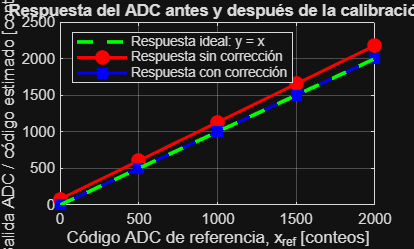

figure; hold on;

h_meas = plot(xref, xmed, 'ro-', ...
    'LineWidth', 1.8, ...
    'MarkerFaceColor', 'r', ...
    'MarkerSize', 7);

h_corr = plot(xref, xcorr, 'bs-', ...
    'LineWidth', 1.8, ...
    'MarkerFaceColor', 'b', ...
    'MarkerSize', 7);

h_ideal = plot(xref, xref, 'g--', ...
    'LineWidth', 2.2);

grid on;
box on;

xlabel('Código ADC de referencia, x_{ref} [conteos]');
ylabel('Salida ADC / código estimado [conteos]');
title('Respuesta del ADC antes y después de la calibración');

legend([h_ideal h_meas h_corr], ...
    {'Respuesta ideal: y = x', ...
     'Respuesta sin corrección', ...
     'Respuesta con corrección'}, ...
    'Location', 'northwest');

**Análisis y conclusiones**

La característica no ideal seleccionada, xmeas=1.05xref+80*x*meas�=1.05*x*ref�+80, introdujo un error sistemático de ganancia del 5% y un offset positivo de 80 conteos. En los cinco puntos analizados, el error absoluto aumentó desde 80 conteos en xref=0*x*ref�=0 hasta 180 conteos en xref=2000*x*ref�=2000. Antes de calibrar, se obtuvo un error absoluto medio de 130 conteos y un RMSE de 134.1641 conteos. Por tanto, usar directamente el conteo no corregido puede conducir a una decisión técnica incorrecta: el sistema interpretaría una entrada nula como 80 conteos y sobreestimaría la señal en todo el rango estudiado.

Al aplicar la corrección de dos puntos de la hoja de datos, xcorr=0.95238095xmeas−76.190476*x*corr�=0.95238095*x*meas�−76.190476, el error máximo, el MAE y el RMSE calculados se redujeron a 0 conteos, lo que equivale a una mejora de RMSE de 100%. Así, la calibración cambia la decisión técnica: el ADC puede utilizarse para mediciones dentro del rango analizado únicamente si se aplica la corrección de ganancia y offset.

Sin embargo, el resultado ideal de 0 conteos se debe a que los cinco datos fueron construidos con exactamente la misma función lineal que se invirtió durante la calibración. En un ADC real permanecen limitaciones por cuantización, ruido, variación térmica, deriva de la referencia de voltaje y no linealidad; por ello, una calibración lineal de dos puntos no garantiza error nulo en operación real.